# DAAP HW1

*Alberto Doimo*

*Paolo Ostan*

## **Talking Instrument creation **

### **Parameters initialization**

clc; close all; clear all;

instr_name = "piano.wav";
speech_name = "speech.wav";
talking_instr_res_name = "talking_instr_res.wav";

### First test with verbose parameters to check functioning of the script

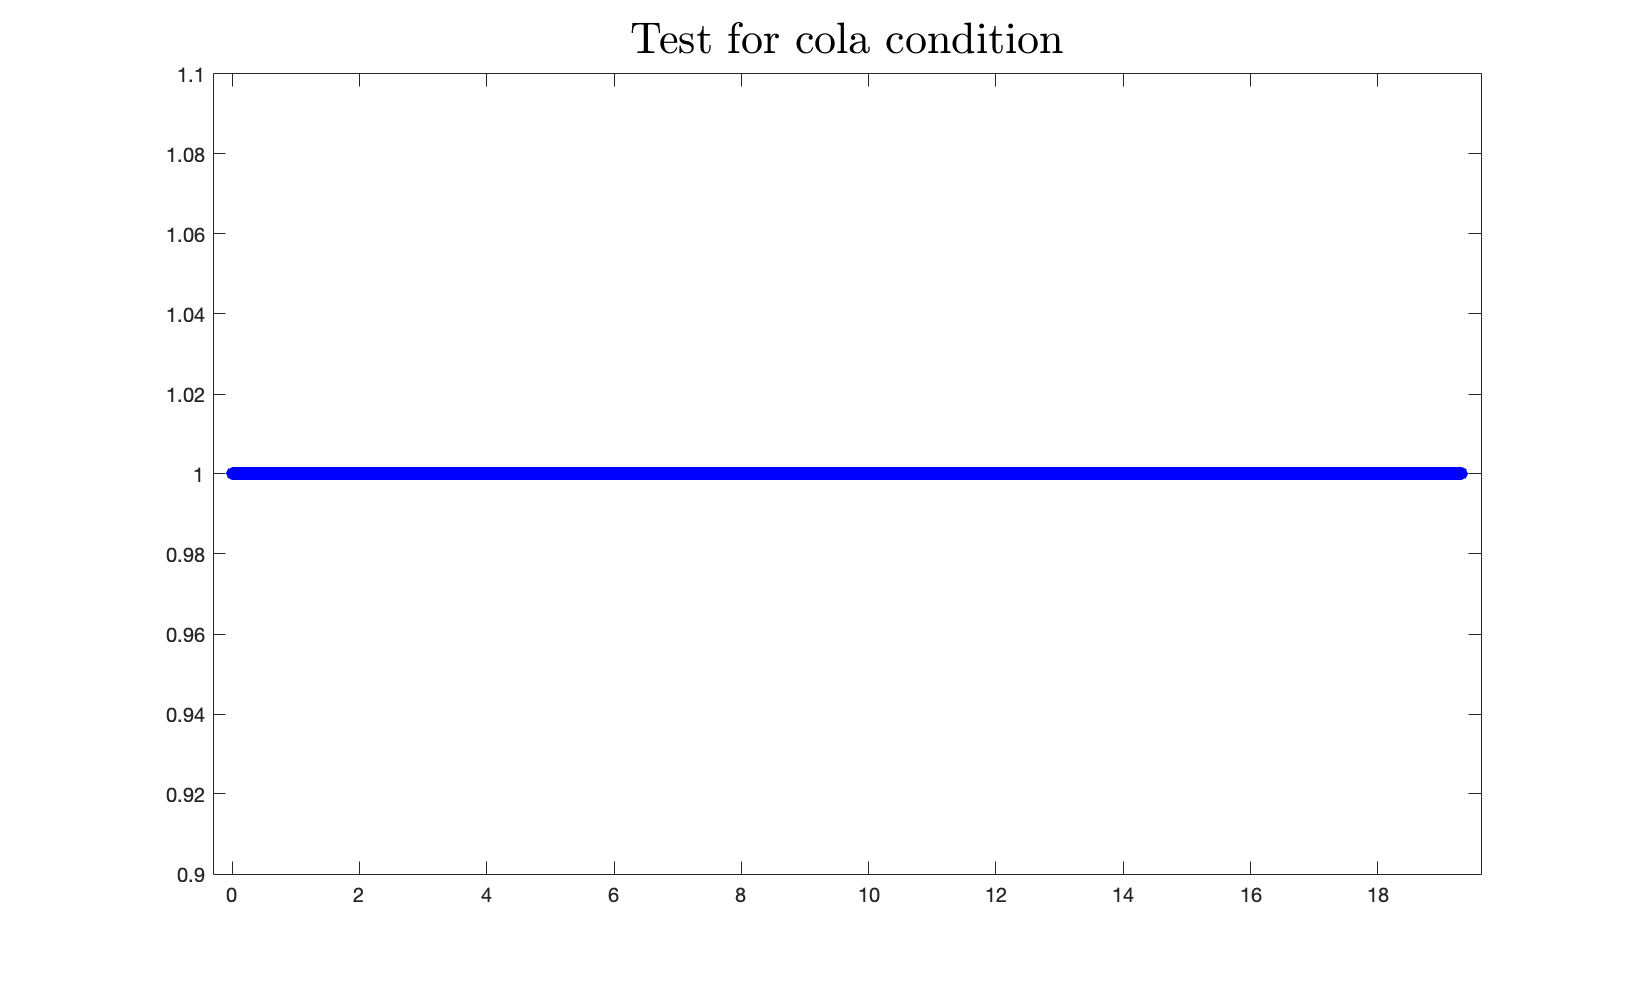

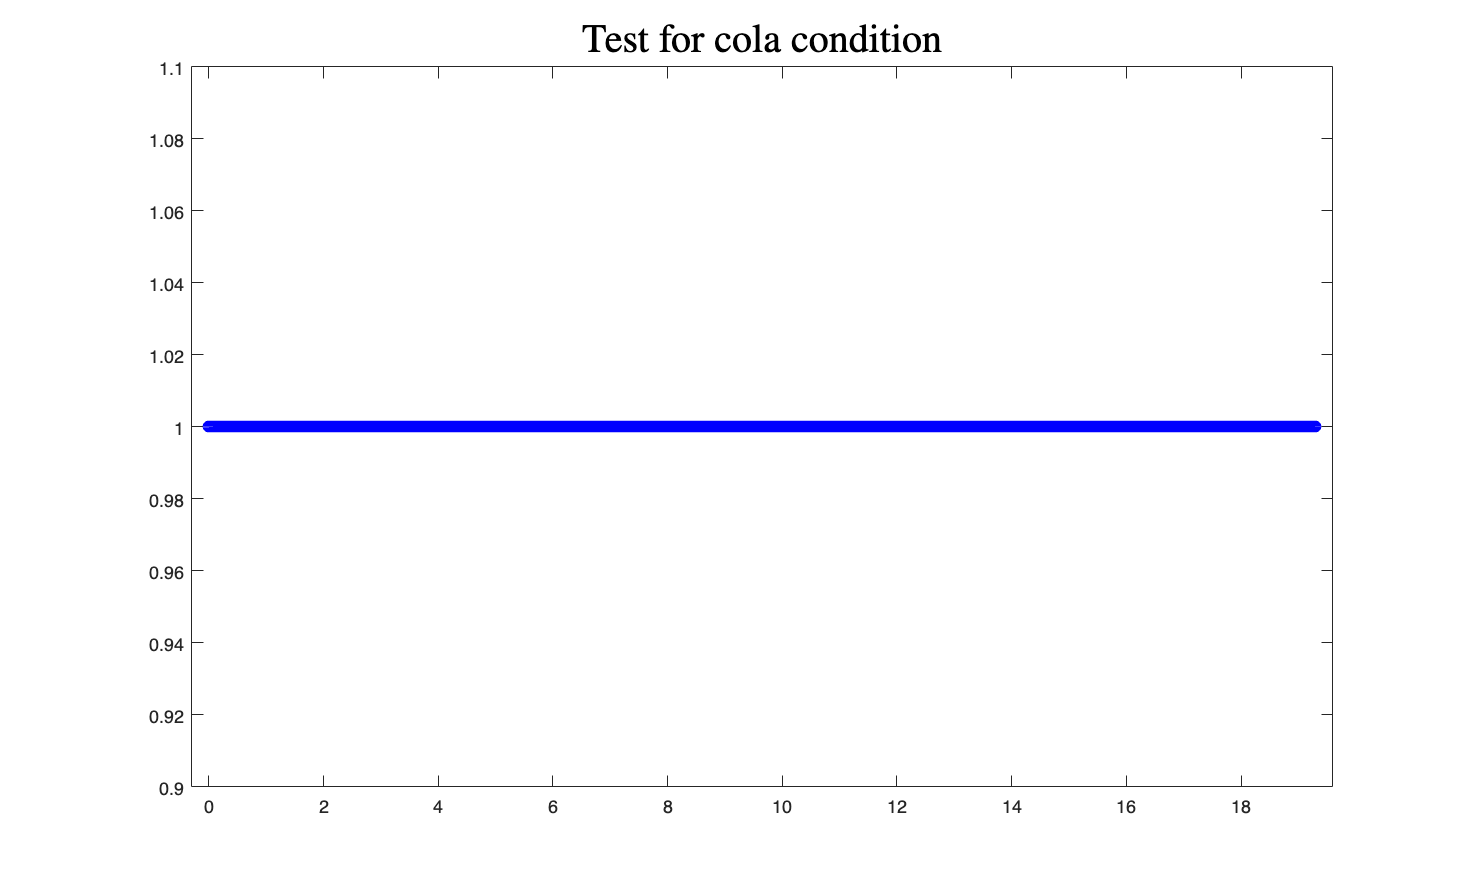

Precision check plots for piano signal


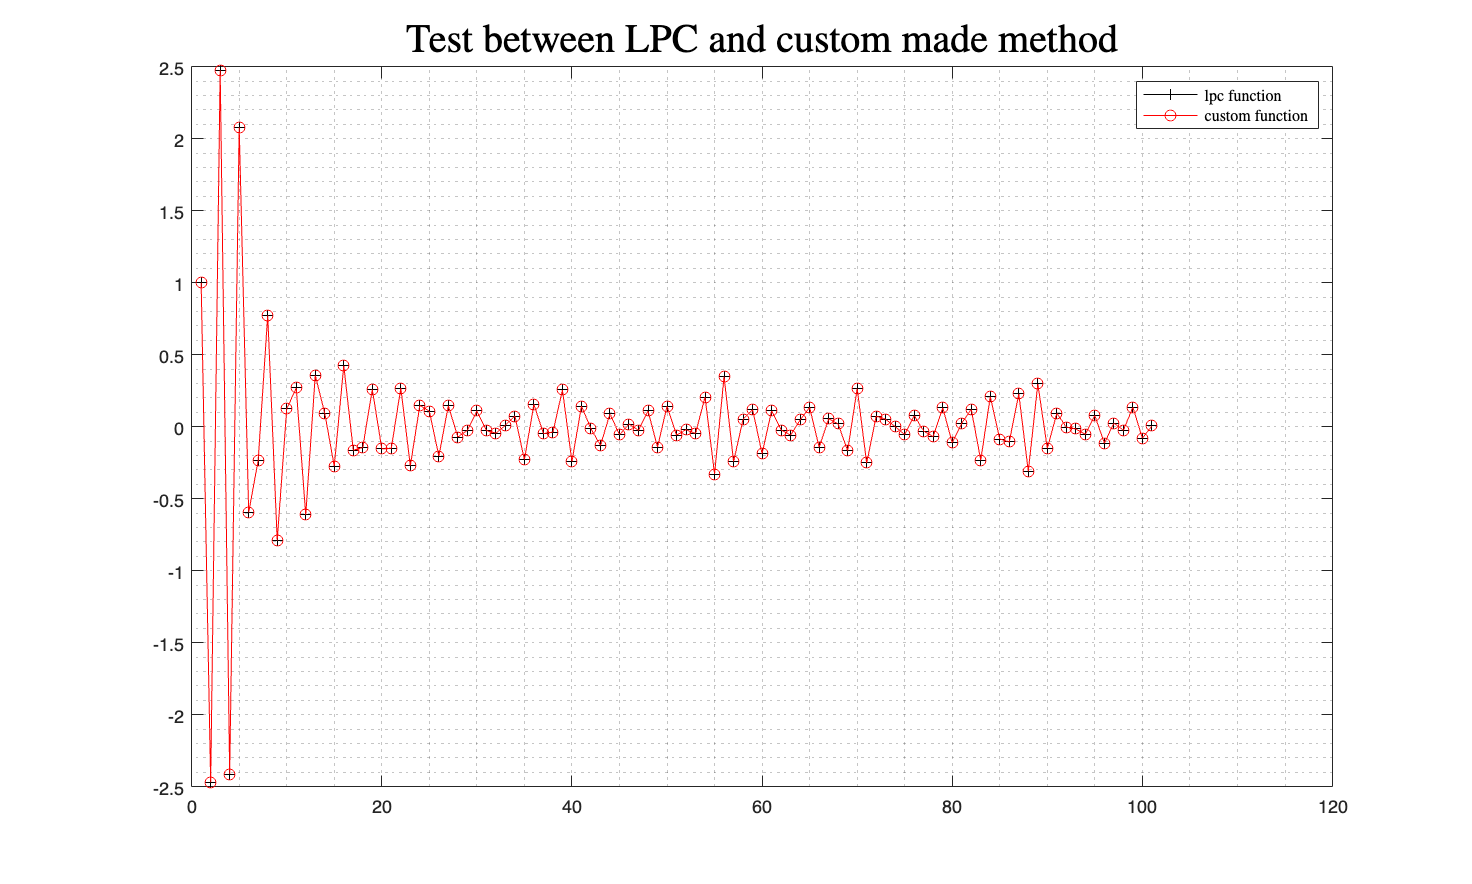

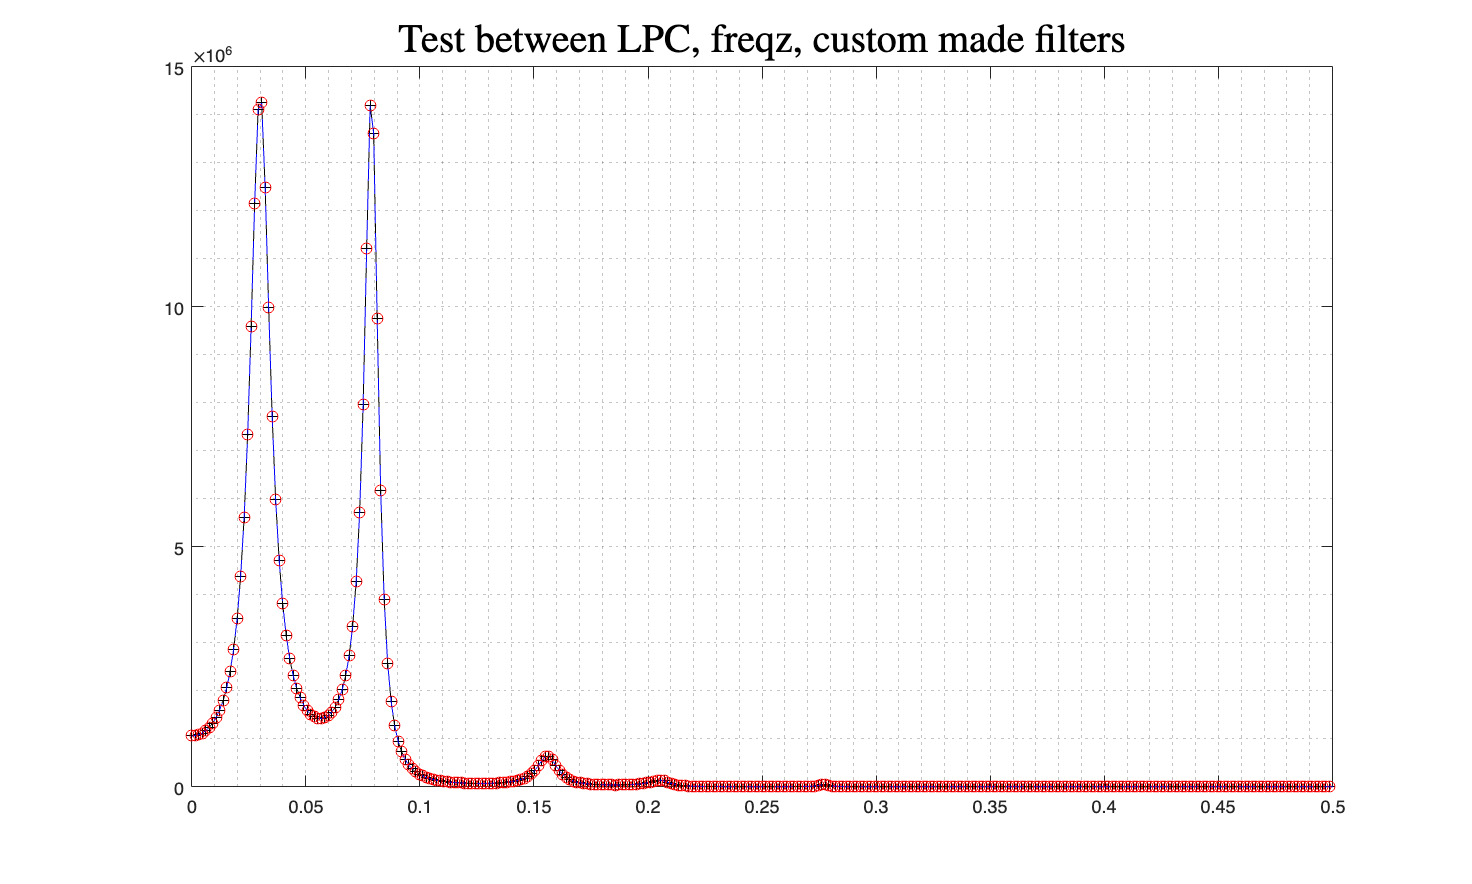

Precision check plots for speech signal


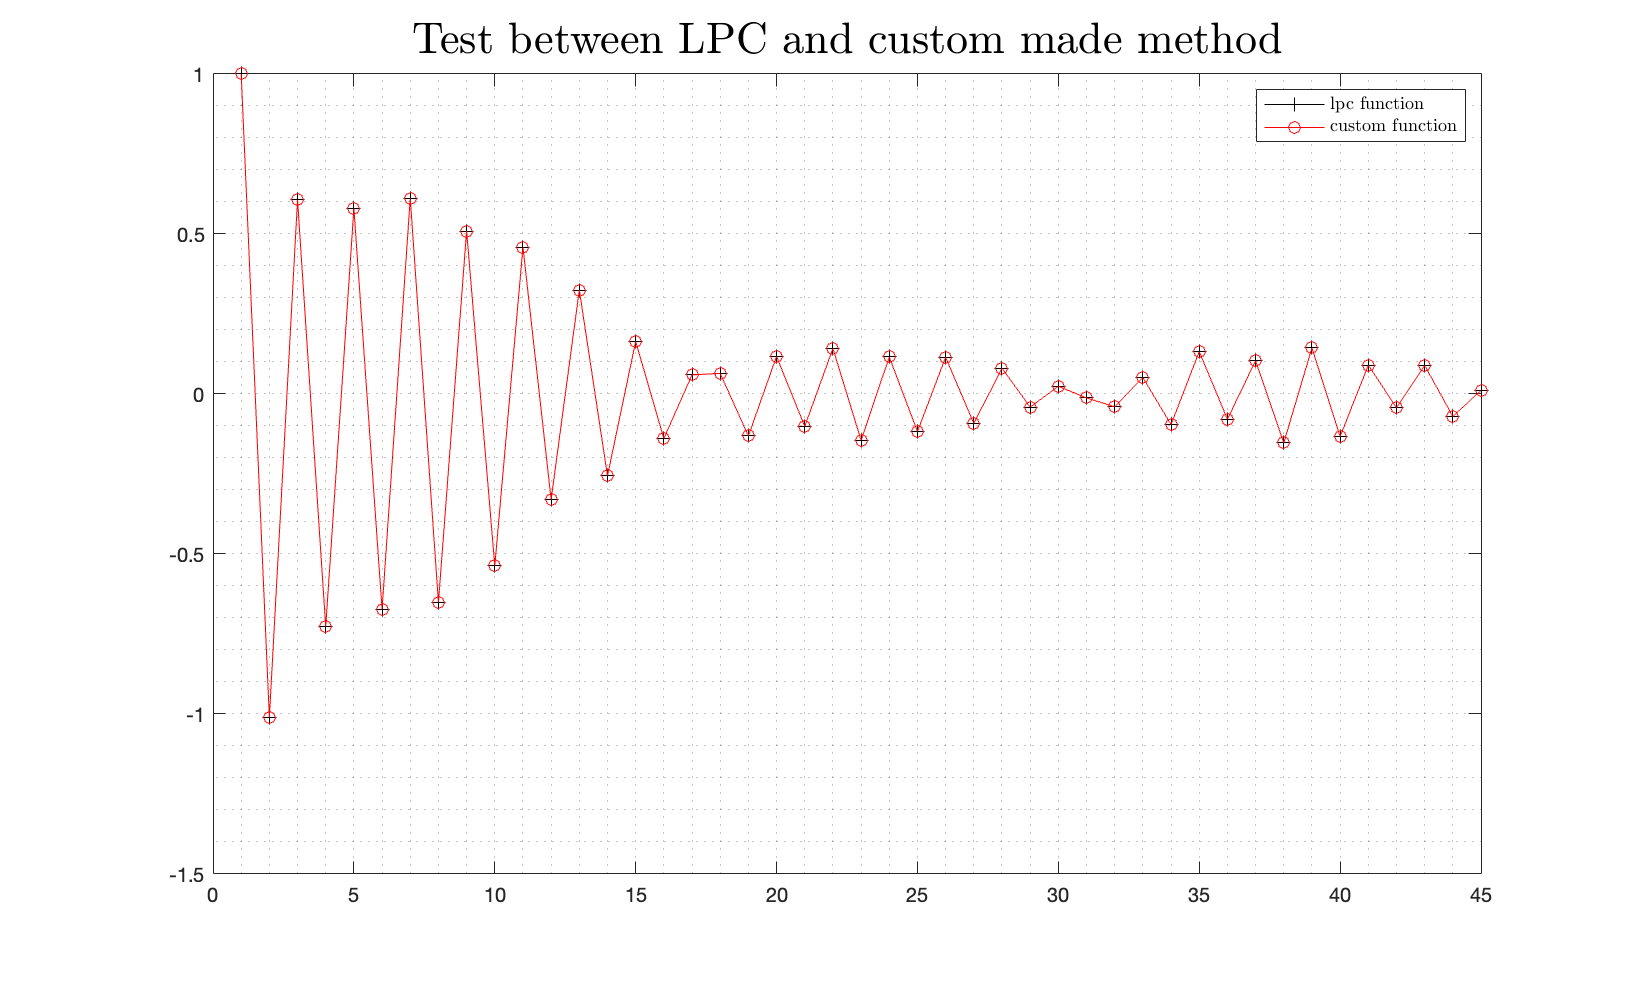

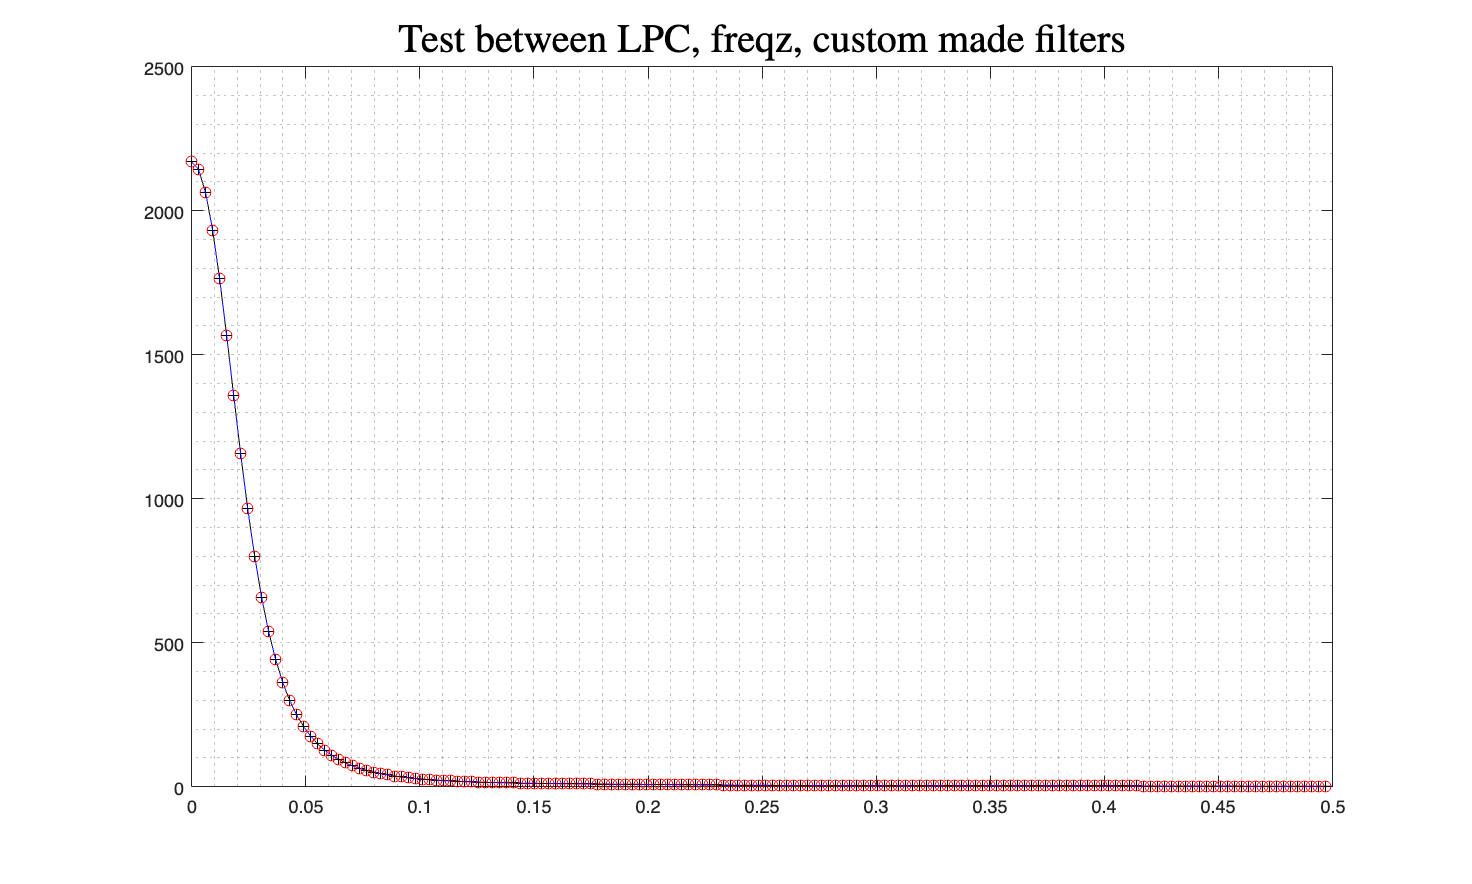

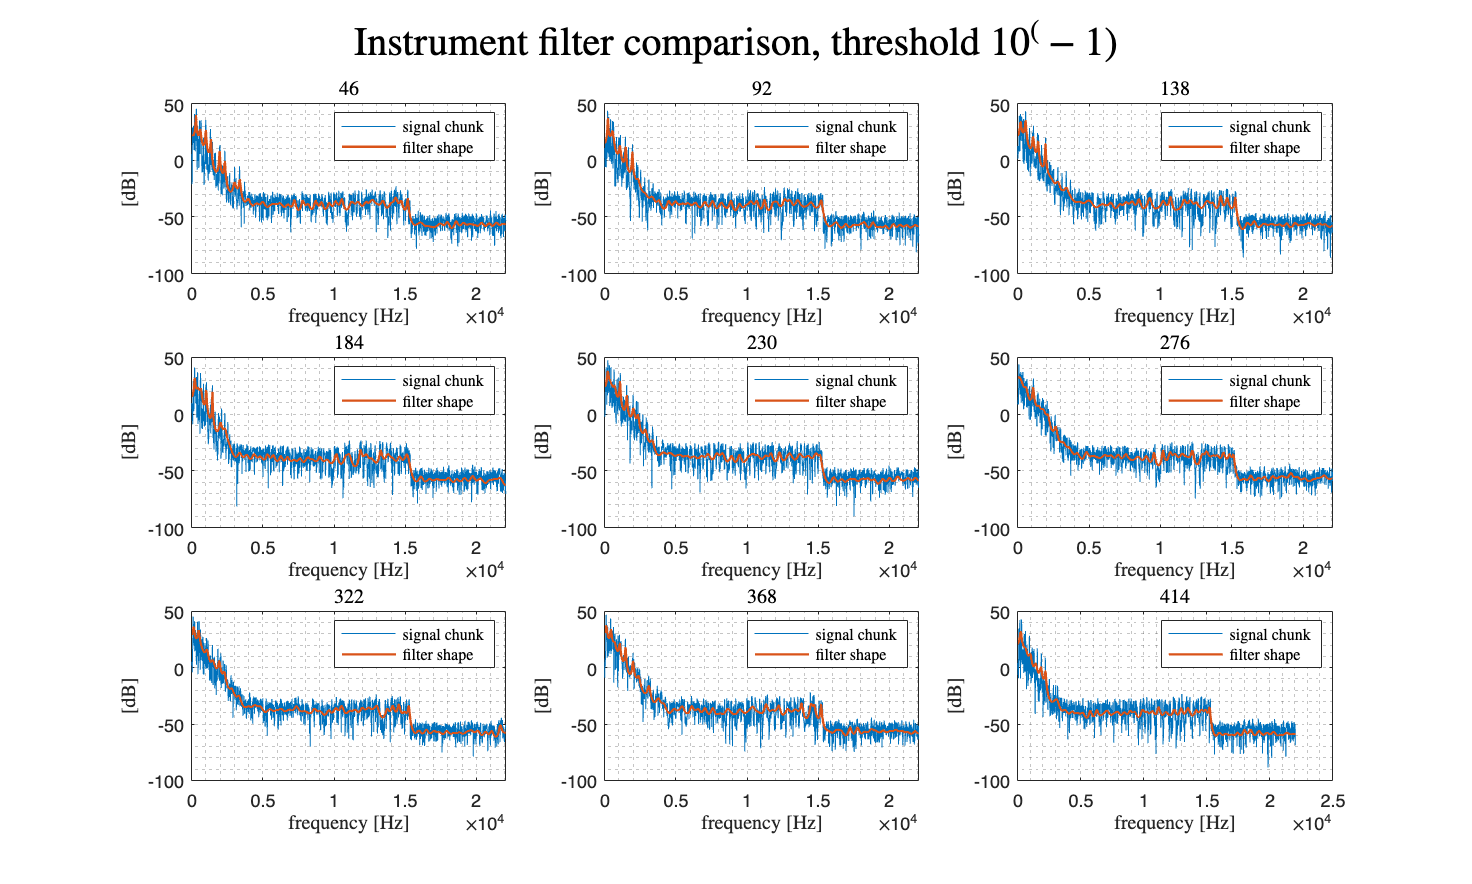

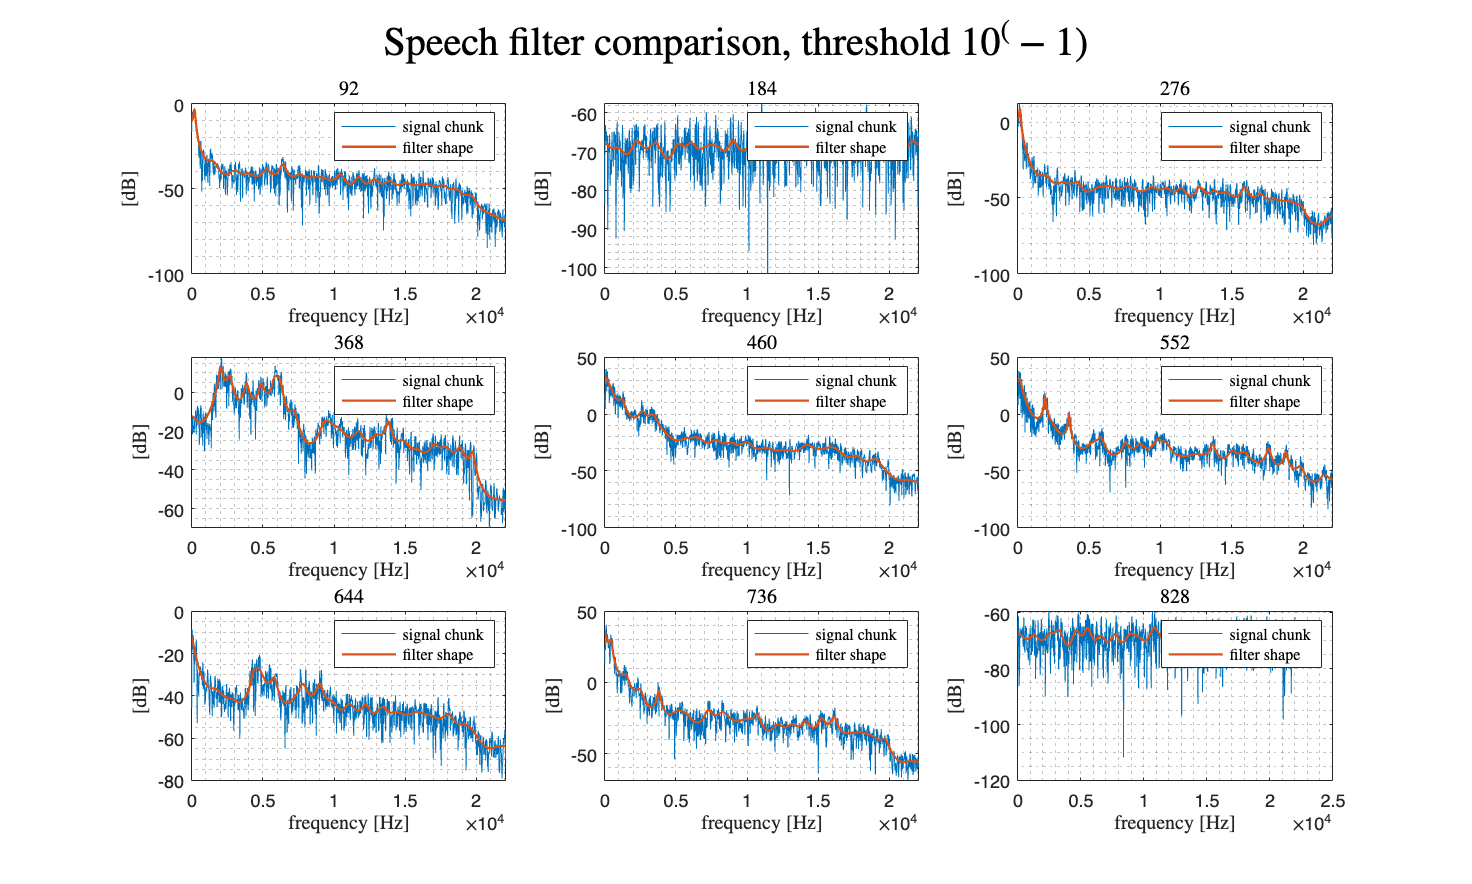

close all;

tic
talking_instr_res_name = "talking_instr_verb1.wav";
main(instr_name, speech_name, talking_instr_res_name,2048,4096,44,100,"linSolve",0.3,10^-1,100000,"zeros",0,0,1,"threshold $10^(-1)$","mean");

toc

Elapsed time is 2.318287 seconds.


## test for various threshold values using steepest descent

close all;clc;
disp("threshold 10^-1")
tic
talking_instr_res_name = "talking_instr_10_1.wav";
main(instr_name, speech_name, talking_instr_res_name,"mixed1",0.3,10^-1,100000,"zeros",1,0,0,"threshold $10^{-1}$");
toc
disp("threshold 10^-2")
tic
talking_instr_res_name = "talking_instr_10_2.wav";
main(instr_name, speech_name, talking_instr_res_name,"mixed1",0.3,10^-2,100000,"zeros",1,0,0,"threshold $10^{-2}$");
toc
disp("threshold 10^-4")

tic
talking_instr_res_name = "talking_instr_10_4.wav";
main(instr_name, speech_name, talking_instr_res_name,"mixed1",0.3,10^-4,100000,"zeros",1,0,0,"threshold $10^{-4}$");
toc

## test for various coefficients initialization values using steepest descent

disp("time for speech steepest descent equals to previous value")

tic
talking_instr_res_name = "talking_instr_zeros.wav";
main(instr_name, speech_name, talking_instr_res_name,"mixed1",0.3,0.5*10^-1,100000,"prev",1,0,0,"prev");
toc
disp("time for speech steepest descent equals to zero")


tic
talking_instr_res_name = "talking_instr_zeros.wav";
main(instr_name, speech_name, talking_instr_res_name,"mixed1",0.3,0.5*10^-1,100000,"zeros",1,0,0,"zeros");
toc
disp("time for speech steepest descent equals to one")

tic

talking_instr_res_name = "talking_instr_ones.wav";
main(instr_name, speech_name, talking_instr_res_name,"mixed1",0.3,0.5*10^-1,100000,"ones",1,0,0,"ones");
toc

disp("time for speech steepest descent equals to random values")


tic
talking_instr_res_name = "talking_instr_randn.wav";
main(instr_name, speech_name, talking_instr_res_name,"mixed1",0.3,0.5*10^-1,100000,"randn",1,0,0,"prev");
toc

%sound(avviso(1:5*44100),44100);